# **Entregable 2 Modelación**

Diego Alejandro Espejo López A01638341

Pablo Heredia Sahagún A01637103

Daniel Esparza Arizpe A01637076

Diego Alberto Cisneros Fajardo A01643454

Se deberán mostrar 4 gráficas:

- Posición contra tiempo

- Velocidad contra tiempo

- Fuerza magnética contra posición

- FEM inducida contra posición

**Programa**

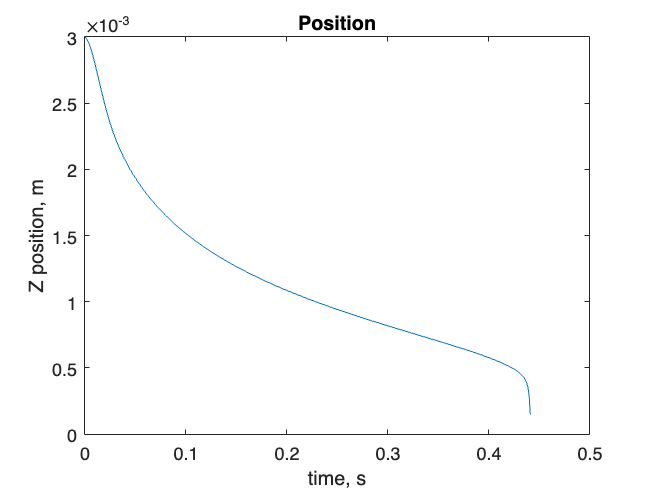

clear; clc;

z0 = 0.003; % P.inicial
z(1) = z0;
mass = 0.003;
Rring = 0.01; % Radio

mo = 4*pi*10^-7; % Permeabilidad del espacio libre
mag = 1; % Momento dipolar magnético
g = -9.81;

E(1) = 0; % Matriz de Corriente Eléctrica
vz(1) = 0; % Matriz de velocidad
t(1) = 0; % Matriz de tiempo
R = 0.001; % Resistencia

dt = 0.001;      
ds = 0.01; 
c = 1; 

[x, y, phi(c), Bz] = B_due_M(z(c), mag, Rring);
while z(c) >= 0
    % Cálculo de variables
    I(c) = E(c)/R; % Corriente
    F(c) = (6*mo*I(c)*Rring^2*z(c)*mag) / (4*((z(c)^2+Rring^2)^(5/2))); % Fuerza ejercida sobre el dipolo
    F(c) = F(c) + (-9.81 * mass); % Sumatoria de Fuerza Gravedad;

    dz = vz(c)*dt + (0.5*(F(c)/mass)*dt^2);
    z(c+1) = z(c) + dz;
    vz(c+1) = dz / dt;

    % Segunda posición
    [x, y, phi(c+1), Bz] = B_due_M(z(c+1), mag, Rring);    %Volvemos a llamar  la funcion pero en la posición siguiente
    E(c+1) = (phi(c+1) - phi(c)) / dt;                          %Voltaje Inducido
    
    if c > 1
        t = 0:dt:(dt*(c-1));
    end

    c = c + 1;
end

% Posición contra tiempo
plot(t(1:c-1), z(1:c-1))
title('Position');
xlabel("time, s");
ylabel("Z position, m");

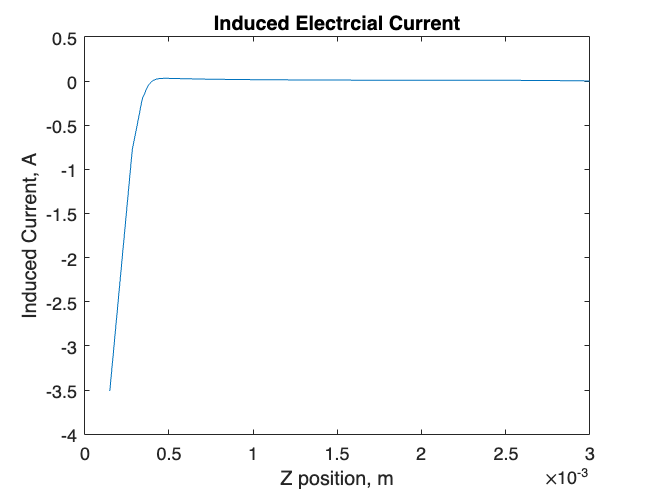


% FEM inducida contra posición
plot(z(1:c-1), E(1:c-1))
title('Induced Electrcial Current');
xlabel("Z position, m");
ylabel("Induced Current, A");

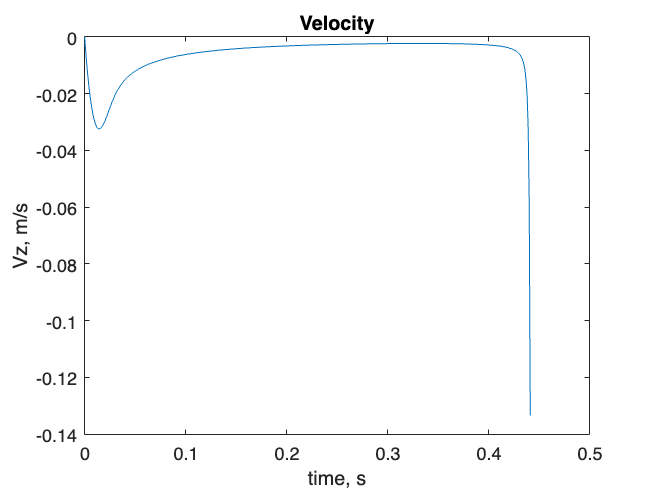


% Velocidad contra tiempo
plot(t(1:c-1), vz(1:c-1))
title('Velocity');
xlabel("time, s");
ylabel("Vz, m/s");

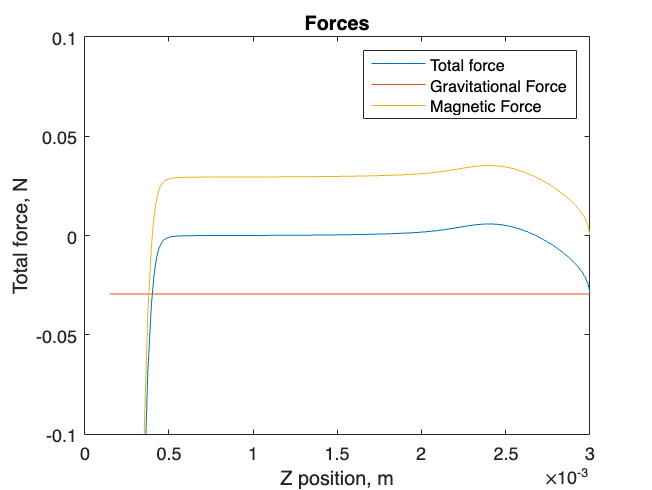


% Fuerza Magnética contra posición
W = ones(1,c-1).*(g*mass);
total = F - W;
plot(z(1:c-1), F(1:c-1))
hold on
plot(z(1:c-1), W);
hold on
plot(z(1:c-1), total);
title('Forces');
xlabel("Z position, m");
ylabel("Total force, N");
legend("Total force", "Gravitational Force", "Magnetic Force")
ylim([-0.1 0.1])

**Función**

function [x,y,phiB,Bz]=B_due_M(z,mag,Rring)
    mo = 4*pi*1e-7;
    ds = 0.005;
    
    x = -Rring:ds:Rring;  
    y = -Rring:ds:Rring; 
    Lx = length(x); 
    Ly = length(y);

    Bz(1:Lx,1:Ly) = 0;
    phiB = 0;
 
    for i = 1:Lx
        for j = 1:Ly
            r = sqrt(x(i)^2+y(j)^2);
            if r < Rring
                Bz(i,j) = mo / (4*pi) * (3*z*(mag*z) - mag * (x(i)^2+y(j)^2+z^2)) / ((x(i)^2+y(j)^2+z^2+(ds/10)^2)^(5/2));
                phiB = phiB + ds^2 * Bz(i,j);
            end
        end
    end
end